clear; clc; close all;

%% =========================
% USER SETTINGS
%% =========================
noiseFile = 'anc_noise_outputs/noise_engine_like.wav';
songFile  = 'song.mp3';

outDir = fullfile('anc_case1_results', 'noise_engine_like');
if ~exist(outDir, 'dir')
    mkdir(outDir);
end

fs_target = 44100;
dur_sec   = 10;

% Use same hyperparameters as Case 2 NLMS baseline
L         = 256;
mu        = 0.10;
delta     = 1e-6;
trainSec  = 2;

noiseGain = 0.9;
songGain  = 0.3;

%% =========================
% LOAD AUDIO
%% =========================
[x_noise, fs1] = audioread(noiseFile);
[song, fs2]    = audioread(songFile);

if size(x_noise,2) > 1
    x_noise = mean(x_noise, 2);
end
if size(song,2) > 1
    song = mean(song, 2);
end

if fs1 ~= fs_target
    x_noise = resample(x_noise, fs_target, fs1);
end
if fs2 ~= fs_target
    song = resample(song, fs_target, fs2);
end

fs = fs_target;

%% =========================
% MATCH LENGTHS
%% =========================
N = min([length(x_noise), length(song), dur_sec*fs]);

x_noise = x_noise(1:N);
song    = song(1:N);

t = (0:N-1)'/fs;

x_noise = x_noise / (max(abs(x_noise)) + 1e-12);
song    = song    / (max(abs(song))    + 1e-12);

%% =========================
% PRIMARY PATH P(z)
% noise source -> ear/listening point
%% =========================
c = 343;

d_ref = 0.20;
d_ear = 0.80;

delayDiff_sec = (d_ear - d_ref) / c;
delaySamples  = round(delayDiff_sec * fs);

P = zeros(200,1);
P(1)   = 0.90;
P(18)  = 0.25;
P(43)  = 0.12;
P(77)  = 0.06;

v0 = filter(P, 1, x_noise);

if delaySamples >= N
    error('delaySamples is too large for the current signal length.');
end

v = [zeros(delaySamples,1); v0(1:end-delaySamples)];
v = v / (max(abs(v)) + 1e-12);
v = noiseGain * v;

%% =========================
% DESIRED SIGNAL + TRAINING PERIOD
%% =========================
s = songGain * song;
trainN = min(round(trainSec * fs), N);
s(1:trainN) = 0;

%% =========================
% PRIMARY SIGNAL AT EAR
%% =========================
d = s + v;

mx = max(abs(d));
if mx > 0.99
    d = 0.99 * d / mx;
end

%% =========================
% CASE 1 NLMS
% No secondary path in Case 1
%% =========================
w = zeros(L,1);
y = zeros(N,1);   % estimated noise
e = zeros(N,1);   % output / residual

for n = L:N
    xvec = x_noise(n:-1:n-L+1);

    y(n) = w.' * xvec;
    e(n) = d(n) - y(n);

    normFactor = delta + xvec.' * xvec;
    w = w + (mu / normFactor) * e(n) * xvec;
end

%% =========================
% METRICS
%% =========================
inputNoise  = d - s;
outputNoise = e - s;

P_before = mean(inputNoise.^2);
P_after  = mean(outputNoise.^2);

suppression_dB = 10*log10(P_before / P_after);

inputSNR_dB  = 10*log10(mean(s.^2) / mean(inputNoise.^2));
outputSNR_dB = 10*log10(mean(s.^2) / mean(outputNoise.^2));
snrImprovement_dB = outputSNR_dB - inputSNR_dB;

MSE_before = mean((d - s).^2);
MSE_after  = mean((e - s).^2);

fprintf('=== Case 1 Offline ANC with NLMS ===\n');

=== Case 1 Offline ANC with NLMS ===


fprintf('Training period   : %.2f s\n', trainSec);

Training period   : 2.00 s


fprintf('Suppression       : %.2f dB\n', suppression_dB);

Suppression       : 22.17 dB


fprintf('Input SNR         : %.2f dB\n', inputSNR_dB);

Input SNR         : -12.82 dB


fprintf('Output SNR        : %.2f dB\n', outputSNR_dB);

Output SNR        : 9.35 dB


fprintf('SNR Improvement   : %.2f dB\n', snrImprovement_dB);

SNR Improvement   : 22.17 dB


fprintf('MSE before        : %.6f\n', MSE_before);

MSE before        : 0.035833


fprintf('MSE after         : %.6f\n', MSE_after);

MSE after         : 0.000217


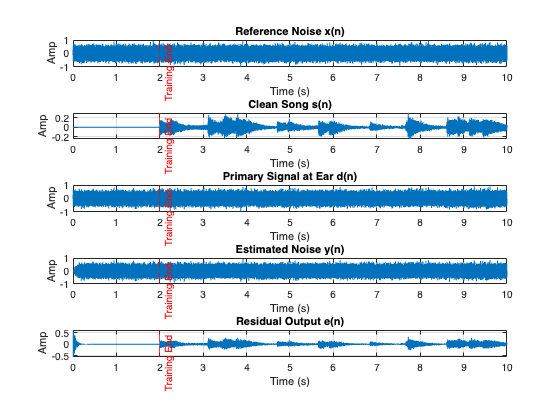


%% =========================
% SAVE AUDIO
%% =========================
normaudio = @(x) x/(max(abs(x))+1e-12);

audiowrite(fullfile(outDir, 'reference_noise.wav'), normaudio(x_noise), fs);
audiowrite(fullfile(outDir, 'clean_song.wav'),      normaudio(s), fs);
audiowrite(fullfile(outDir, 'primary_ear_signal.wav'), normaudio(d), fs);
audiowrite(fullfile(outDir, 'estimated_noise.wav'), normaudio(y), fs);
audiowrite(fullfile(outDir, 'anc_output.wav'),      normaudio(e), fs);

%% =========================
% TIME-DOMAIN PLOTS
%% =========================
figure;
subplot(5,1,1);
plot(t, x_noise); grid on;
xline(trainSec, '--r', 'Training End');
title('Reference Noise x(n)');
xlabel('Time (s)'); ylabel('Amp');

subplot(5,1,2);
plot(t, s); grid on;
xline(trainSec, '--r', 'Training End');
title('Clean Song s(n)');
xlabel('Time (s)'); ylabel('Amp');

subplot(5,1,3);
plot(t, d); grid on;
xline(trainSec, '--r', 'Training End');
title('Primary Signal at Ear d(n)');
xlabel('Time (s)'); ylabel('Amp');

subplot(5,1,4);
plot(t, y); grid on;
xline(trainSec, '--r', 'Training End');
title('Estimated Noise y(n)');
xlabel('Time (s)'); ylabel('Amp');

subplot(5,1,5);
plot(t, e); grid on;
xline(trainSec, '--r', 'Training End');
title('Residual Output e(n)');
xlabel('Time (s)'); ylabel('Amp');

saveas(gcf, fullfile(outDir, 'time_domain_signals.png'));

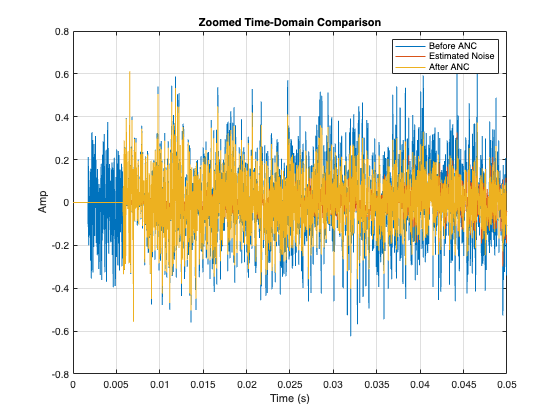


%% =========================
% ZOOMED TIME-DOMAIN PLOT
%% =========================
figure;
idx = 1:min(round(0.05*fs), N);
plot(t(idx), d(idx), 'LineWidth', 1); hold on;
plot(t(idx), y(idx), 'LineWidth', 1);
plot(t(idx), e(idx), 'LineWidth', 1);
grid on;
legend('Before ANC', 'Estimated Noise', 'After ANC');
title('Zoomed Time-Domain Comparison');
xlabel('Time (s)');
ylabel('Amp');
saveas(gcf, fullfile(outDir, 'time_zoom_before_after.png'));

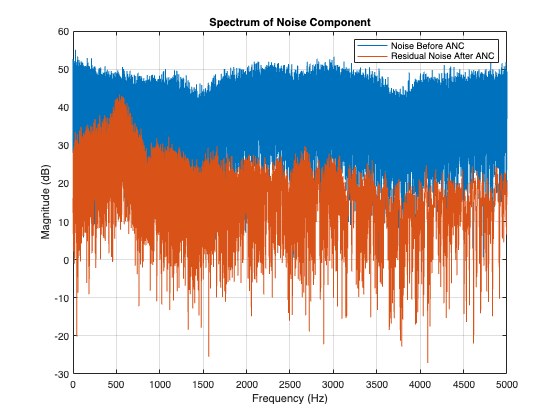


%% =========================
% FREQUENCY-DOMAIN PLOTS
%% =========================
Nfft = 2^nextpow2(N);
f = (0:Nfft/2-1)' * fs / Nfft;

D  = fft(d, Nfft);
Y  = fft(y, Nfft);
E  = fft(e, Nfft);
VN = fft(inputNoise, Nfft);
VO = fft(outputNoise, Nfft);

magD  = 20*log10(abs(D(1:Nfft/2))  + 1e-12);
magY  = 20*log10(abs(Y(1:Nfft/2))  + 1e-12);
magE  = 20*log10(abs(E(1:Nfft/2))  + 1e-12);
magVN = 20*log10(abs(VN(1:Nfft/2)) + 1e-12);
magVO = 20*log10(abs(VO(1:Nfft/2)) + 1e-12);

figure;
plot(f, magD, 'LineWidth', 1); hold on;
plot(f, magY, 'LineWidth', 1);
plot(f, magE, 'LineWidth', 1);
xlim([0 5000]);
grid on;
legend('Before ANC', 'Estimated Noise', 'After ANC');
title('Spectrum of Output Signals');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
saveas(gcf, fullfile(outDir, 'spectrum_before_after.png'));

figure;
plot(f, magVN, 'LineWidth', 1); hold on;
plot(f, magVO, 'LineWidth', 1);
xlim([0 5000]);
grid on;
legend('Noise Before ANC', 'Residual Noise After ANC');
title('Spectrum of Noise Component');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
saveas(gcf, fullfile(outDir, 'noise_spectrum_before_after.png'));

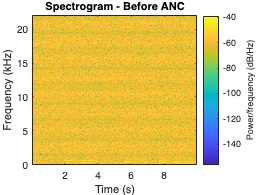


%% =========================
% SPECTROGRAMS
%% =========================
figure;
spectrogram(d, 1024, 768, 1024, fs, 'yaxis');
title('Spectrogram - Before ANC');
saveas(gcf, fullfile(outDir, 'spectrogram_before.png'));

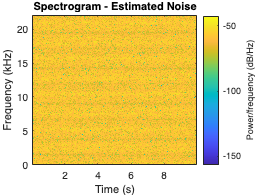


figure;
spectrogram(y, 1024, 768, 1024, fs, 'yaxis');
title('Spectrogram - Estimated Noise');
saveas(gcf, fullfile(outDir, 'spectrogram_estimated_noise.png'));

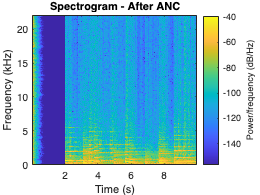


figure;
spectrogram(e, 1024, 768, 1024, fs, 'yaxis');
title('Spectrogram - After ANC');
saveas(gcf, fullfile(outDir, 'spectrogram_after.png'));

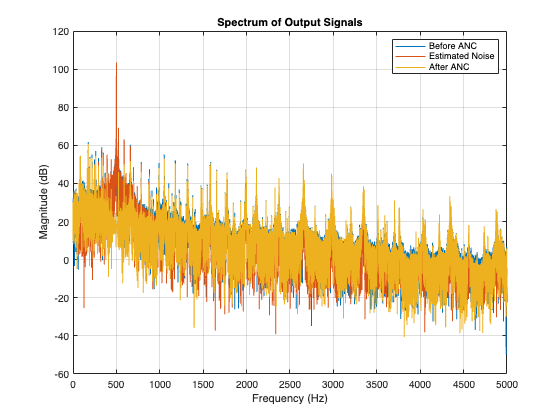

All results saved.



%% =========================
% SAVE TEXT SUMMARY
%% =========================
fid = fopen(fullfile(outDir, 'results_summary.txt'), 'w');
fprintf(fid, 'Case 1 Offline ANC with NLMS\n');
fprintf(fid, 'Noise file                 : %s\n', noiseFile);
fprintf(fid, 'Song file                  : %s\n', songFile);
fprintf(fid, 'Sample rate                : %d Hz\n', fs);
fprintf(fid, 'Duration                   : %.2f s\n', N/fs);
fprintf(fid, 'Training period            : %.2f s\n', trainSec);
fprintf(fid, 'Filter length              : %d\n', L);
fprintf(fid, 'Step size mu               : %.4f\n', mu);
fprintf(fid, 'Primary path model         : delayed FIR\n');
fprintf(fid, 'No secondary path          : yes\n');
fprintf(fid, 'Speed of sound             : %.1f m/s\n', c);
fprintf(fid, 'Source-to-reference dist   : %.2f m\n', d_ref);
fprintf(fid, 'Source-to-ear dist         : %.2f m\n', d_ear);
fprintf(fid, 'Additional delay           : %d samples\n', delaySamples);
fprintf(fid, 'Suppression                : %.2f dB\n', suppression_dB);
fprintf(fid, 'Input SNR                  : %.2f dB\n', inputSNR_dB);
fprintf(fid, 'Output SNR                 : %.2f dB\n', outputSNR_dB);
fprintf(fid, 'SNR Improvement            : %.2f dB\n', snrImprovement_dB);
fprintf(fid, 'MSE before                 : %.6f\n', MSE_before);
fprintf(fid, 'MSE after                  : %.6f\n', MSE_after);
fclose(fid);

disp('All results saved.');